n_x = 0

n_x = 0

n_y = 0

n_y = 0

n_z = 0

n_z = 0

filename = 'quantum_energy_transitions_0-0-0.csv'

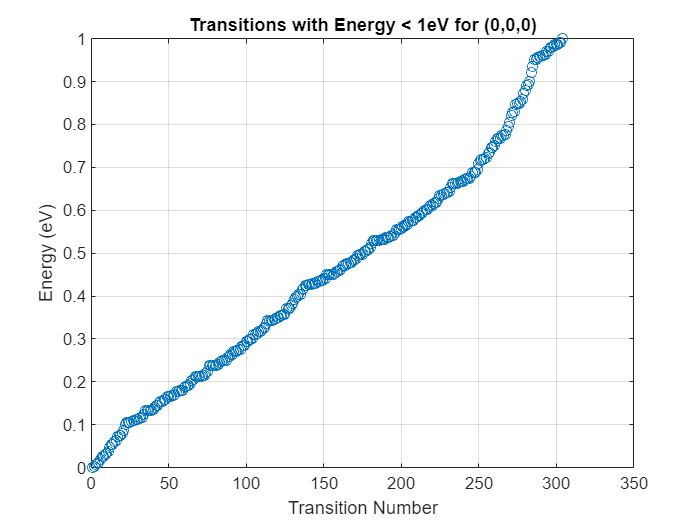

Number of transitions less than 1 eV: 304


n_x = 1

n_y = 0

n_z = 0

filename = 'quantum_energy_transitions_1-0-0.csv'

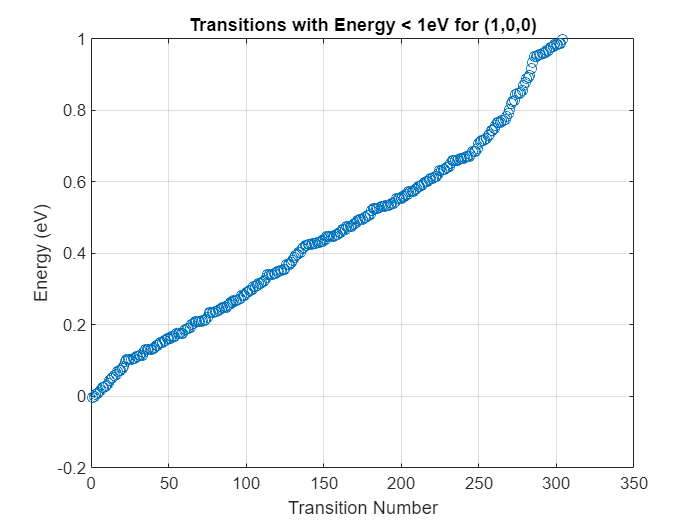

Number of transitions less than 1 eV: 304


n_x = 0

n_y = 1

n_z = 0

filename = 'quantum_energy_transitions_0-1-0.csv'

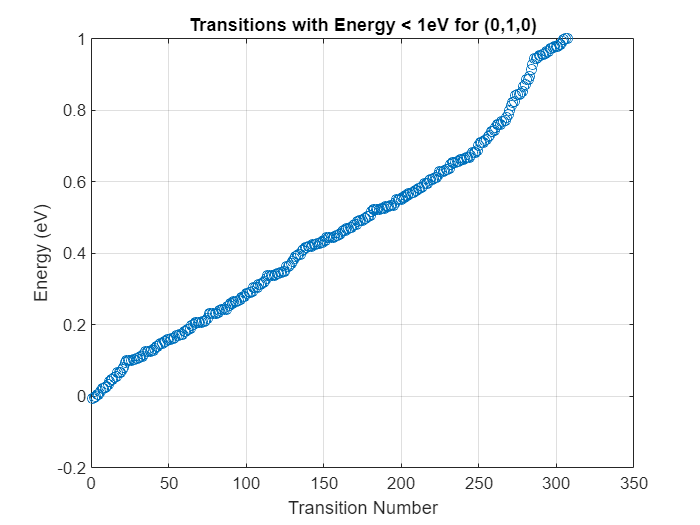

Number of transitions less than 1 eV: 307


% Load the table from the CSV file
for idx=1:3
     switch idx
        case 2
            n_x = 1
            n_y = 0
            n_z = 0
        case 3
            n_x = 0
            n_y = 1
            n_z = 0
    end
    filename = append('quantum_energy_transitions_', int2str(n_x), '-', int2str(n_y), '-', int2str(n_z), '.csv')
    quantum_table = readtable(filename);
    
    % Sort the table by the energy transition column
    sorted_table = sortrows(quantum_table, 'Energy_Transition_eV');
    
    % Filter to find transitions less than 1 eV
    transitions_less_than_1eV = sorted_table(sorted_table.Energy_Transition_eV < 1, :);
    
    % Count the number of transitions less than 1 eV
    num_transitions_less_than_1eV = height(transitions_less_than_1eV);
    
    % Plotting
    figure;
    plot(1:num_transitions_less_than_1eV, transitions_less_than_1eV.Energy_Transition_eV, 'o');
    xlabel('Transition Number');
    ylabel('Energy (eV)');

    tit = append('Transitions with Energy < 1eV for (', int2str(n_x), ',', int2str(n_y), ',', int2str(n_z), ')');
    title(tit);
    grid on;
    
    % Display the number of transitions less than 1 eV
    disp(['Number of transitions less than 1 eV: ', num2str(num_transitions_less_than_1eV)]);
end